%2025.09.05
%产生扫频干扰数据作为分类数据,干扰JNR=30-60dB，扫频周期40-80us，扫频带宽20Mhz
close all;clear;clc
j=sqrt(-1);
data_num=1;     %干扰样本数
num_label = 7;  %信号标签
samp_num=8000;  %距离窗点数

fs = 80e6;          % 采样频率 80MHz
ts = 1/fs;          % 采样时间间隔
T = 100e-6;         % 信号时宽 100μs
N = round(T*fs);    % 采样点数
t = (0:N-1)*ts;     % 时间窗口
% t = linspace(0,taup,taup*fs);          %时间序列

%% 1.定义线性调频信号
taup = 20e-6;       % 信号脉宽 20μs
Ntau = round(taup*fs);    % 采样点数
ttau = (-Ntau/2:1:Ntau/2-1)*ts;     % LFM时间窗口
B  = 10e6;          % 信号带宽 10MHz
fc = 0e6           % 中心频率 40MHz

fc = 0

JNR = 50

Bj = 5

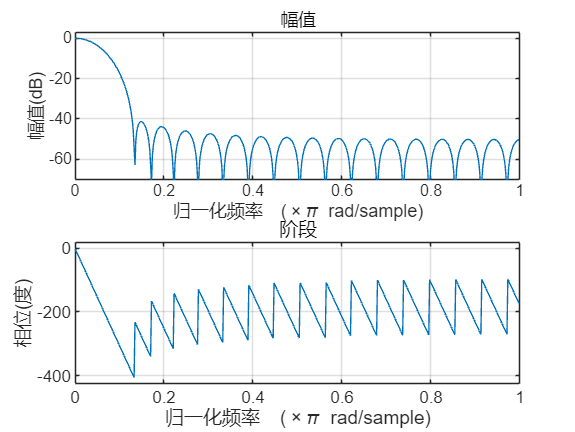

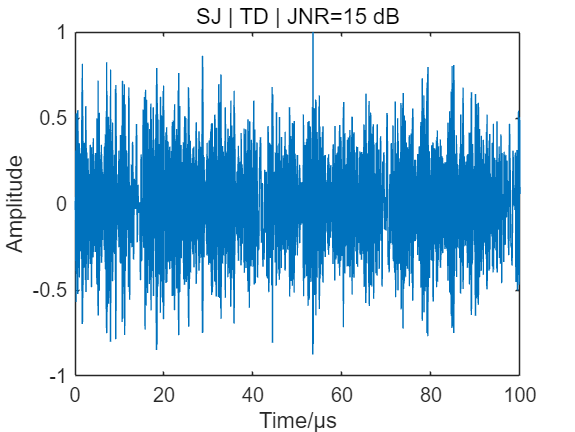

window = 128

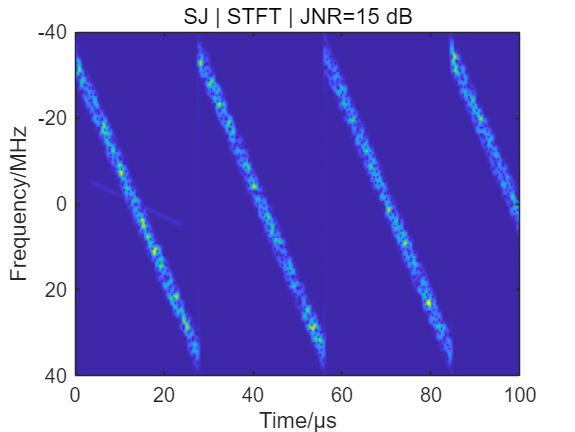

f0 = fc - B/2;      % 起始频率
f1 = fc + B/2;      % 终止频率
% lfm = exp(1j*2*pi*(f0*ttau + (B/(2*taup))*ttau.^2));
lfm = exp(1j*pi*B/taup*ttau.^2);          %LFM信号

SNR=15; %信噪比dB
echo=zeros(data_num,samp_num,3);     %矩阵大小（500,samp_num,2）
echo_stft=zeros(data_num,100,247,3);  %矩阵大小（500,200,1000,2）
label=zeros(1,data_num)+num_label;                         %标签数据,此干扰标签为0

for m=1:data_num
    JNR=50 %+round(rand(1,1)*30); %干噪比30-60dB
    Bj = 5 %扫频带宽
    T=20*1e-6+round((rand(1,1)*20))*1e-6;%扫频周期20-40us
    B1 = 7*B;
    f0 = fc - B1/2;            % 起始频率
    K = B1/T;                  % 调频斜率
    N = 6;                     % 总时长 N 个扫频周期
    t1 = linspace(0, N*T, N*T*fs);   
    
    % 把时间折返到 [0, T)
    t_mod = mod(t1, T);
    
    % 周期性 LFM
    swept = exp(1j*2*pi*( f0*t_mod + 0.5*K*t_mod.^2 ));
    swept = swept(1:samp_num);
    jam=swept;
    spp=randn([1,length(jam)])+1j*randn([1,length(jam)]);%噪声基底
    
    lpFilt = fir1(34, Bj*1e6/(fs),chebwin(35,30)); 
    freqz(lpFilt,1)
    spp = filter(lpFilt, 1, spp);
    tj = (0:samp_num-1)/fs;


     jam=swept.*spp;
    x=(1+square(0.25*pi*10^6*t1,60))/2;
    % jam=jam.*x;
    
    sp=randn([1,samp_num])+1j*randn([1,samp_num]);%噪声基底
    white_noise = sp;
    sp1=sp;
    sp=sp/std(sp);
    As=10^(SNR/20);%目标回波幅度
    Aj=10^(JNR/20);%干扰回波幅度
    range_tar=1+round(rand(1,1)*1400);
    
    sp(1+range_tar:length(lfm)+range_tar)=sp(1+range_tar:length(lfm)+range_tar)+As*lfm;  %噪声+目标回波 目标在距离窗内200点处
    if length(jam)<1001
        sp(1:length(jam))=sp(1:length(jam))+Aj*jam;
        sp(length(jam)+1:2*length(jam))=sp(length(jam)+1:2*length(jam))+Aj*jam;
    else
        sp(1:length(jam))=sp(1:length(jam))+Aj*jam;
        noise_echo(1:length(jam)) = 0*sp(1:length(jam))+Aj*jam;
    end
    pure_echo = 0*sp;
    pure_echo(1+range_tar:length(lfm)+range_tar) = pure_echo(1+range_tar:length(lfm)+range_tar)+As*lfm;
    

    sp=sp/max(max(sp));
    sp_abs=abs(sp);
     figure(3)
    plot(linspace(0,100,samp_num),sp);
    title(sprintf('SJ | TD | JNR=%d dB', SNR));
    xlabel('Time/μs'); ylabel('Amplitude');

    echo(m,1:samp_num,1)=real(sp); 
    echo(m,1:samp_num,2)=imag(sp);
    echo(m,1:samp_num,3)=sp_abs; 
    echo(m,1:samp_num,4)=angle(sp); %信号实部、虚部分开存入三维张量中
    window = 128    
    [S,F,T] = spectrogram(sp,window,window-8,400,fs, 'centered');
 
   
   
    S=S/max(max(S));
    S_abs=abs(S);
    figure(4)
    imagesc(linspace(0,100,size(S,1)),linspace(-40,40,size(S,2)),abs(S));
    
    title(sprintf('SJ | STFT | JNR=%d dB', SNR)); 
    ylabel('Frequency/MHz'); xlabel('Time/μs');
    
    echo_stft(m,1:size(S,1),1:size(S,2),1)=real(S);
    echo_stft(m,1:size(S,1),1:size(S,2),2)=imag(S);
    echo_stft(m,1:size(S,1),1:size(S,2),3)=S_abs;
    echo_stft(m,1:size(S,1),1:size(S,2),4)=angle(S);
    
end

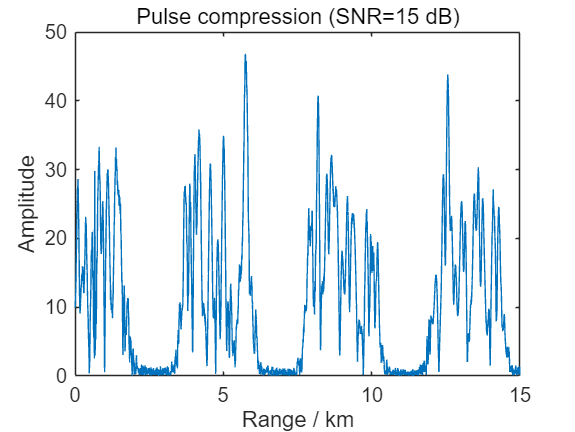

% --- 匹配滤波脉冲压缩 ---
s_ref = lfm;                    % 参考信号 (一定要和生成时一致)
h = conj(flip(s_ref));
y = conv(sp, h);
Np = length(s_ref);
y_aligned = y(Np:end);          % 对齐
env = abs(y_aligned);
env_dB = 10*log10(env.^2 / max(env.^2));


% 距离轴
c = 3e8;
rng_axis = (0:length(env)-1) * c/(2*fs);

% 绘图
figure;
% plot(rng_axis*1e-3, env_dB);
% xlabel('Range / km'); ylabel('Power (dB)');

plot(rng_axis*1e-3, env);
xlabel('Range / km'); ylabel('Amplitude');
title(sprintf('Pulse compression (SNR=%d dB)', SNR));